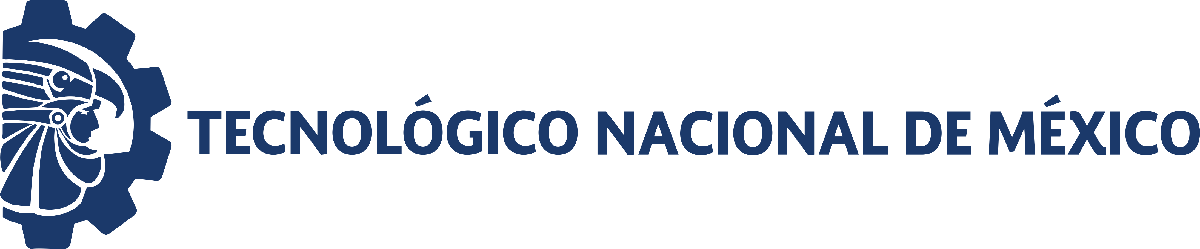                                 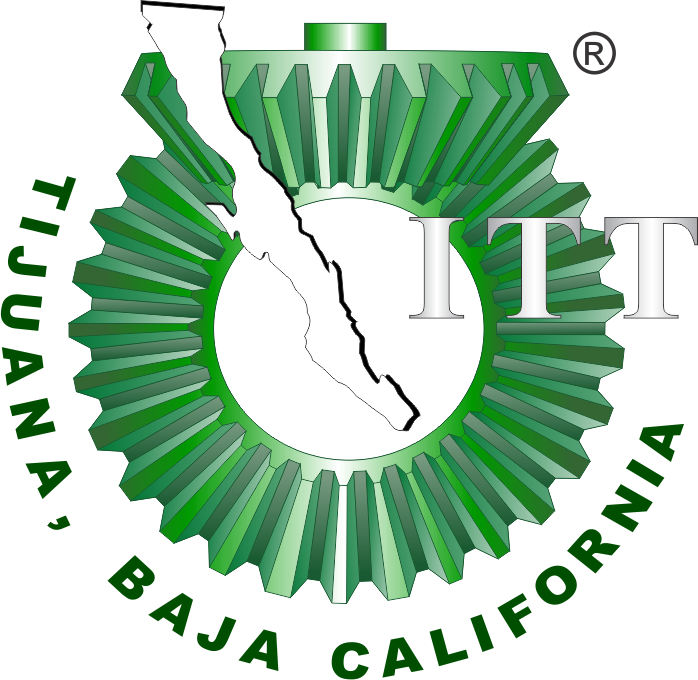

# Práctica 4: Sistema Sanguineo

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

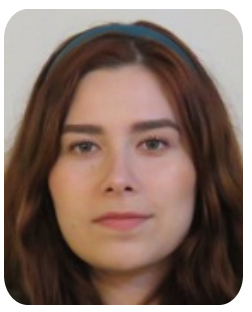

Nombre del alumno: **Kenia Cardenas Manzo **

Número de control: **20210773**

Correo institucional: **kenia.cardenas201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all'); format short
tend = 180; %tiempo de simulacion en dias
dt= 1E-3; % intervalo de integracion para el metodo de solucion por diferencias finitas
n= round(tend/dt); %cantidad de iteraciones para el metodo numerico
%condiciones iniciales base para cada paciente
x1_0= 59; x2_0=44; x3_0=885;

%parametros particulares para cada paciente
gamma= [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta= [1.650; 0.867; 1.617; 2.615; 1.518; 3.676; 0.891; 2.557; 0.925; 0.879];

seed = 20210773; %semilla para asegurar reproducibilidad
rng(seed,'twister')
%intervalo de las condiciones iniciales
xmin= 0.99; xmax=1.01;
interval= xmin + (xmin - xmax).*rand(numel(gamma),1);

%condiciones iniclaes para cada paciente

x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');...


x1(0) = 
   58.0425   57.3207   57.7950   58.0761   57.6536   57.3691   57.5715   58.3476   57.7985   58.0392



x2(0) = 
   43.2859   42.7477   43.1013   43.3110   42.9959   42.7838   42.9346   43.5135   43.1039   43.2835



x3(0) = 
  870.6372  859.8108  866.9248  871.1411  864.8042  860.5372  863.5718  875.2141  866.9770  870.5877



## **Función:   Modelo Matematico**

function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %parametros fijos del sistema
    Base = 855.42; X0 = 7.3785; k1= 0.125 ; k2= 0.1667 ; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 =zeros(n+1,1); x1(1)= x1_0; 
    x2 =zeros(n+1,1); x2(1)= x2_0; 
    x3 =zeros(n+1,1); x3(1)= x3_0; 
    
    for i = 1:n %metodo euler
        x1(i+1) = x1(i)+(beta*(X0-k1*x1(i)) + gamma*(Base - x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i)+(beta*k1*x1(i)- k2*x2(i))*dt;
        x3(i+1) = x3(i)+(beta*(k2*x2(i) - alpha*x3(i)) -u(i)*x3(i))*dt;
    end

end    


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_3 -\alpha x_3 \right)-u\left(t\right)x_3$$


## **Función:   Soluciones en el tiempo**

function plotdata(t,x1,x2,x3,fig)
set(figure(fig), 'color', 'w')
set(gcf,'units','centimeters','position',[1,1,20,20])


mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;
                0,171,169;
                170,0,255;
                109,135,100;
                27,161,226]/255;



subplot(3,1,1)
hold on; grid off; box on; colororder(mycolors);
plot(t,x1)
xlabel('$t$ $ [days]$', 'Interpreter','latex','FontSize',10)
ylabel('$x_1(t)$ ', 'Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5', ...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

set(L, 'FontSize',9,'Box','off','Location','NorthEastOutside')    
set(gca, 'Fontname','Times New Roman','FontSize',10)

subplot(3,1,2)
hold on; grid off; box on; colororder(mycolors);
plot(t,x2)
xlabel('$t$ $ [days]$', 'Interpreter','latex','FontSize',10)
ylabel('$x_2(t)$', 'Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)

L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5', ...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

set(L, 'FontSize',9,'Box','off','Location','NorthEastOutside') 
set(gca, 'Fontname','Times New Roman','FontSize',10)

subplot(3,1,3)
hold on; grid off; box on; colororder(mycolors);
plot(t,x3)
xlabel('$t$ $ [days]$', 'Interpreter','latex','FontSize',10)
ylabel('$x_3(t)$', 'Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)

L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5', ...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'Fontname','Times New Roman','FontSize',10)

set(L, 'FontSize',9,'Box','off','Location','NorthEastOutside') 
set(gca, 'Fontname','Times New Roman','FontSize',10)

if fig == 1
    exportgraphics(gcf,'Caso sin transfusiones.pdf','ContentType','vector')
    exportgraphics(gcf,'Caso sin transfusiones.png','ContentType','vector')

elseif fig==2

    exportgraphics(gcf,'Caso con transfusiones.pdf','ContentType','vector')
    exportgraphics(gcf,'Caso con transfusiones.png','ContentType','vector')
end
end

## **Caso: Sin transfusion sanguinea **

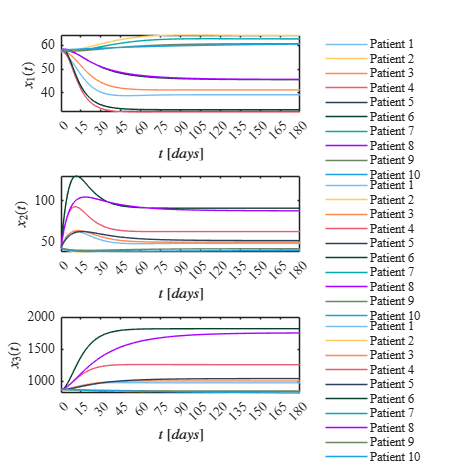

u = zeros(n+1,1); %no hay transfusion
fig = 1; 
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i), beta(i), gamma(i), u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## **Caso: Con transfusion sanguinea [u(t)=1[t1,t2]]**

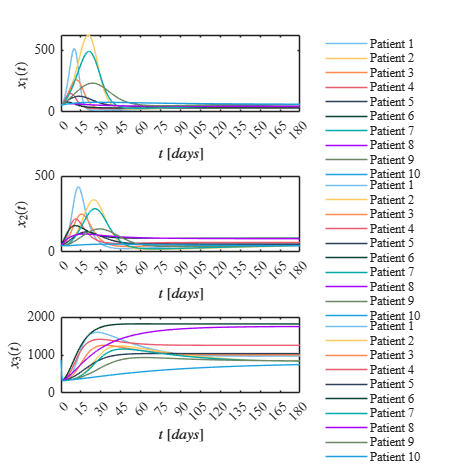

u2 = zeros(n+1,1); u2(1:1000) = 1; % hay transfusion
fig = 2; 
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i), beta(i), gamma(i),u2,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end